## Bzによるモード計算用コード(微分信号)

## get vaccum TF only shot

clear all;
% z t r
% TF 4kV
date = 230119;
shot_num = 2;
low_n_folder = strcat('C:\Users\uswk0\OneDrive\ドキュメント\GitHub\test-open\道家\卒論\data\',num2str(date),'/');

% 生信号読み込み
raw_signal = read_datafile(shot_num,low_n_folder);

% もろもろの係数よみこみ
calib_coefficient = zeros(1,24);
 % probe positionによるベクトル方向
direction = ...
   [1,1,1,1,1,1,...
    -1,1,1,-1,1,1,...
    1,1,1,-1,1,1,...
    1,1,1,1,1,1];
for i = 1:8
    calib_coefficient((i-1)*3+1:(i-1)*3+3) = [37.7,41.6,133]*10^-6;
end

% 生信号を微分信号に変換
% rearrange to 1-24 in channel number according to labels on cable
dBdt_TF_only(:,1:24) = raw_signal(:,2:25)./calib_coefficient.*direction;

% 時間列
%toroidal_mode_B = toroidal_mode_raw(:,2:25)*1000;
time_array = raw_signal(:,1);

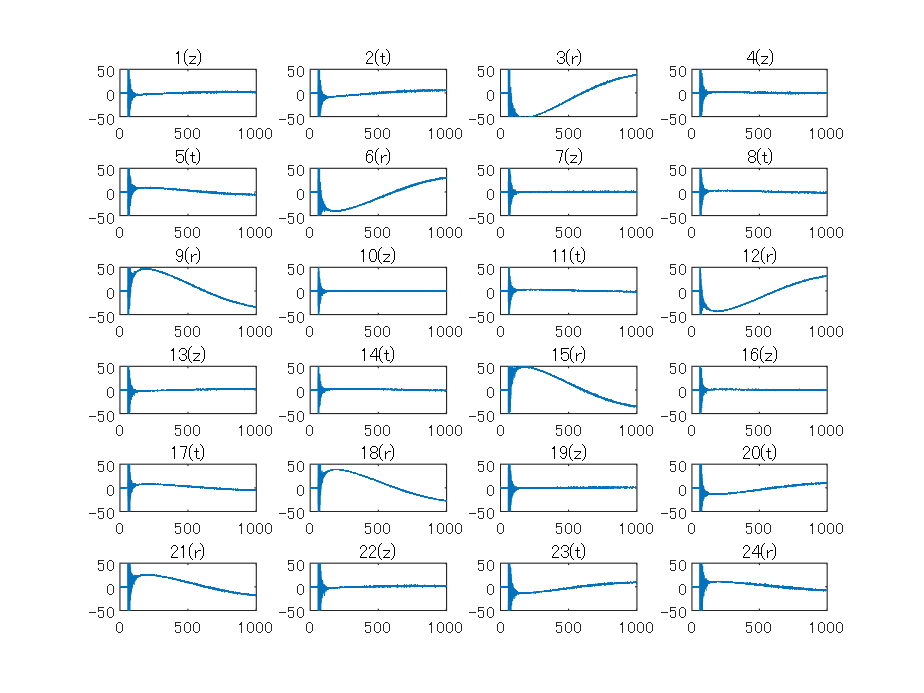

% check all V signals 
% raw signal [mV]
for i = 1:24
    subplot(6,4,i)
    plot(time_array, raw_signal(:,i+1)*10^3);
    %xlabel('us');
    %ylabel('mV')
    ylim([-50 50]);
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
end

% plotting setting
t_start = 0;
t_end = 1000;

y_upperlim = 400;
y_lowerlim = -400;

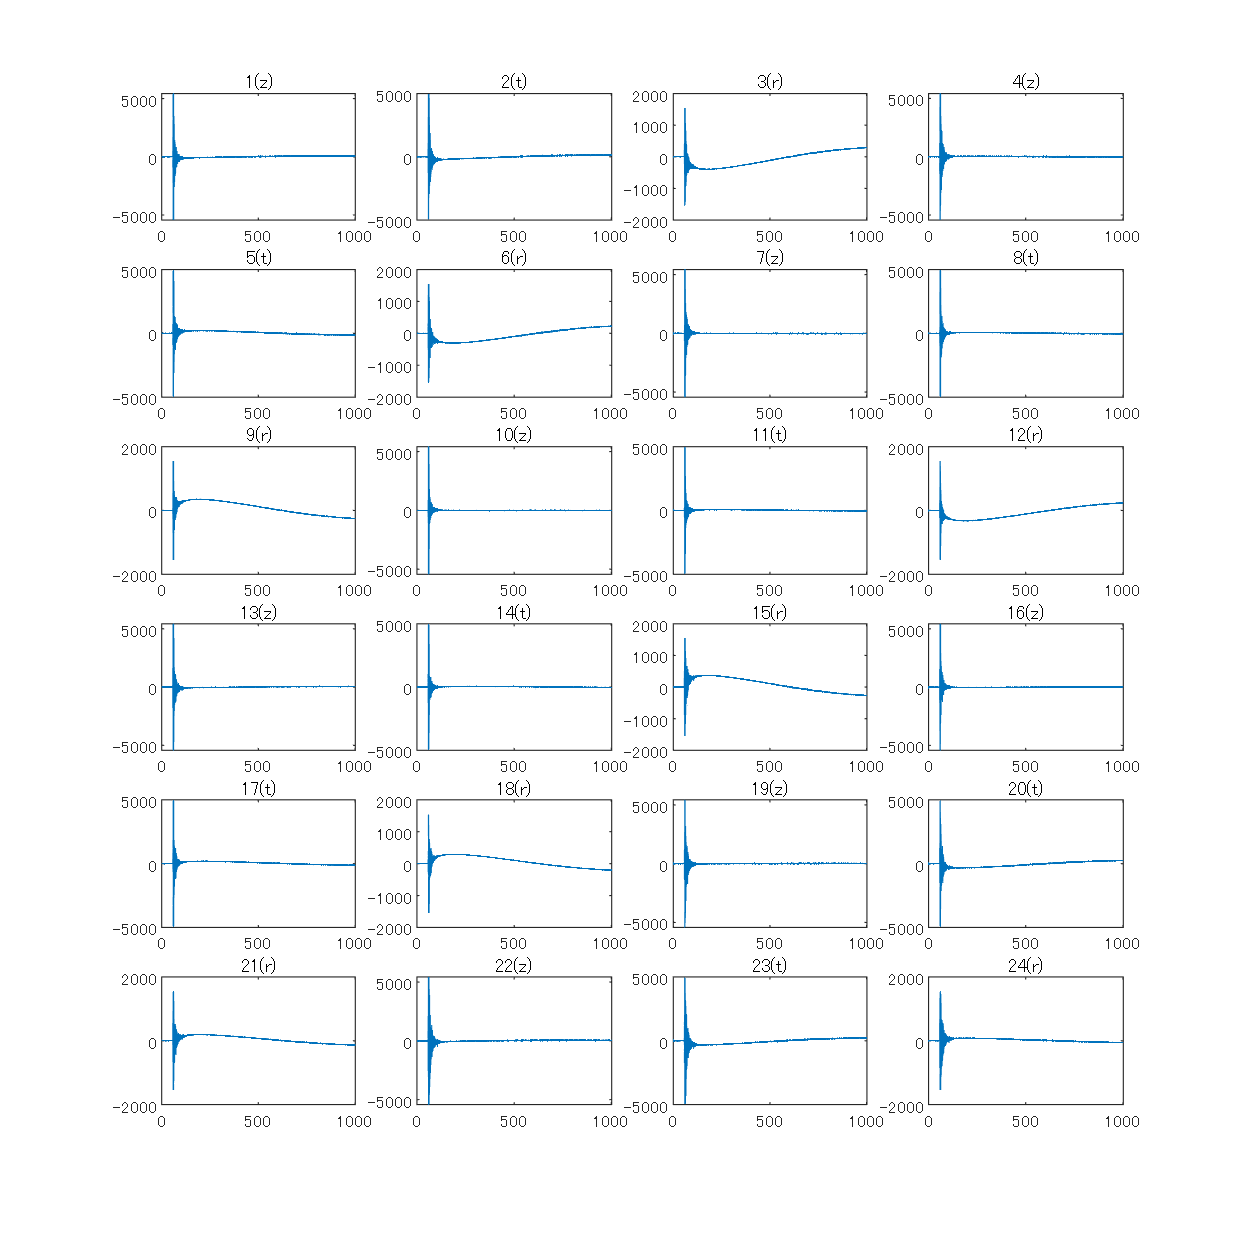

% check all dB/dt signals 
% raw signal [mV]
for i = 1:24
    subplot(6,4,i)
    hold off
    plot(time_array, dBdt_TF_only(:,i));
    %xlabel('us');
    %ylabel('mV')
    %ylim([-50 50]);
    component_all = ['r','z','t'];
    component = component_all(rem(i,3)+1);
    title([num2str(i),'(',component,')'])
    
end

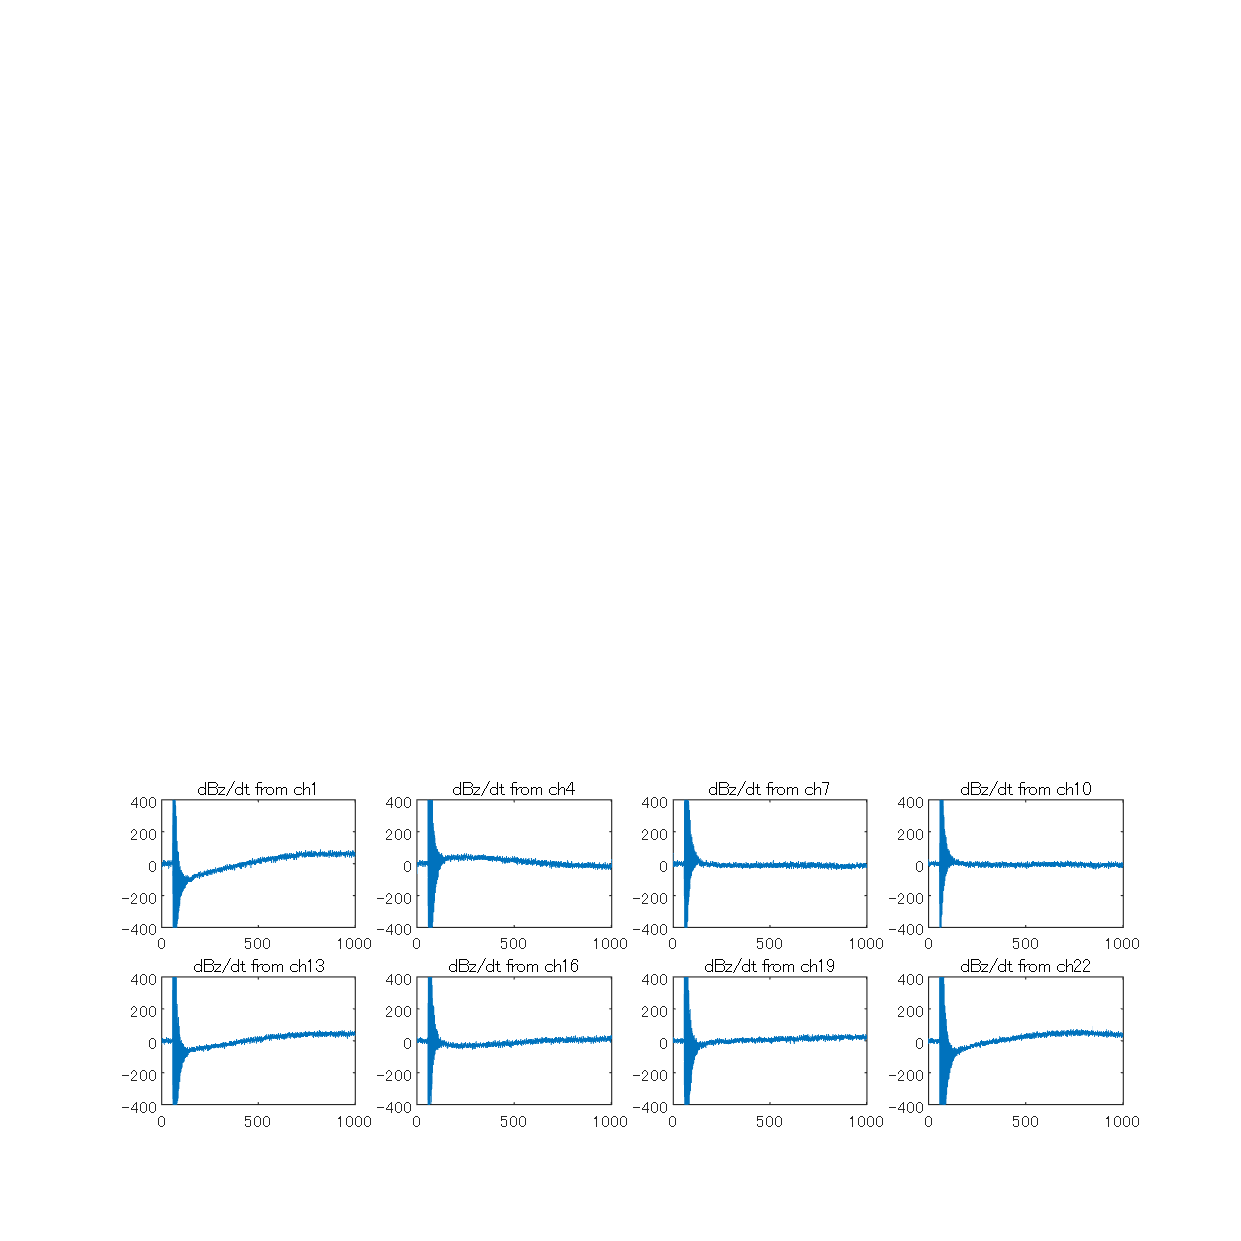

% TFのdBz/dt信号
for i = 1:8
    index_bz = i*3-2;
    subplot(2,4,i)
    plot(time_array,smooth(dBdt_TF_only(:,index_bz)));
    ylim([-400 400]);
    title(['dBz/dt from ch',num2str(index_bz)])
end

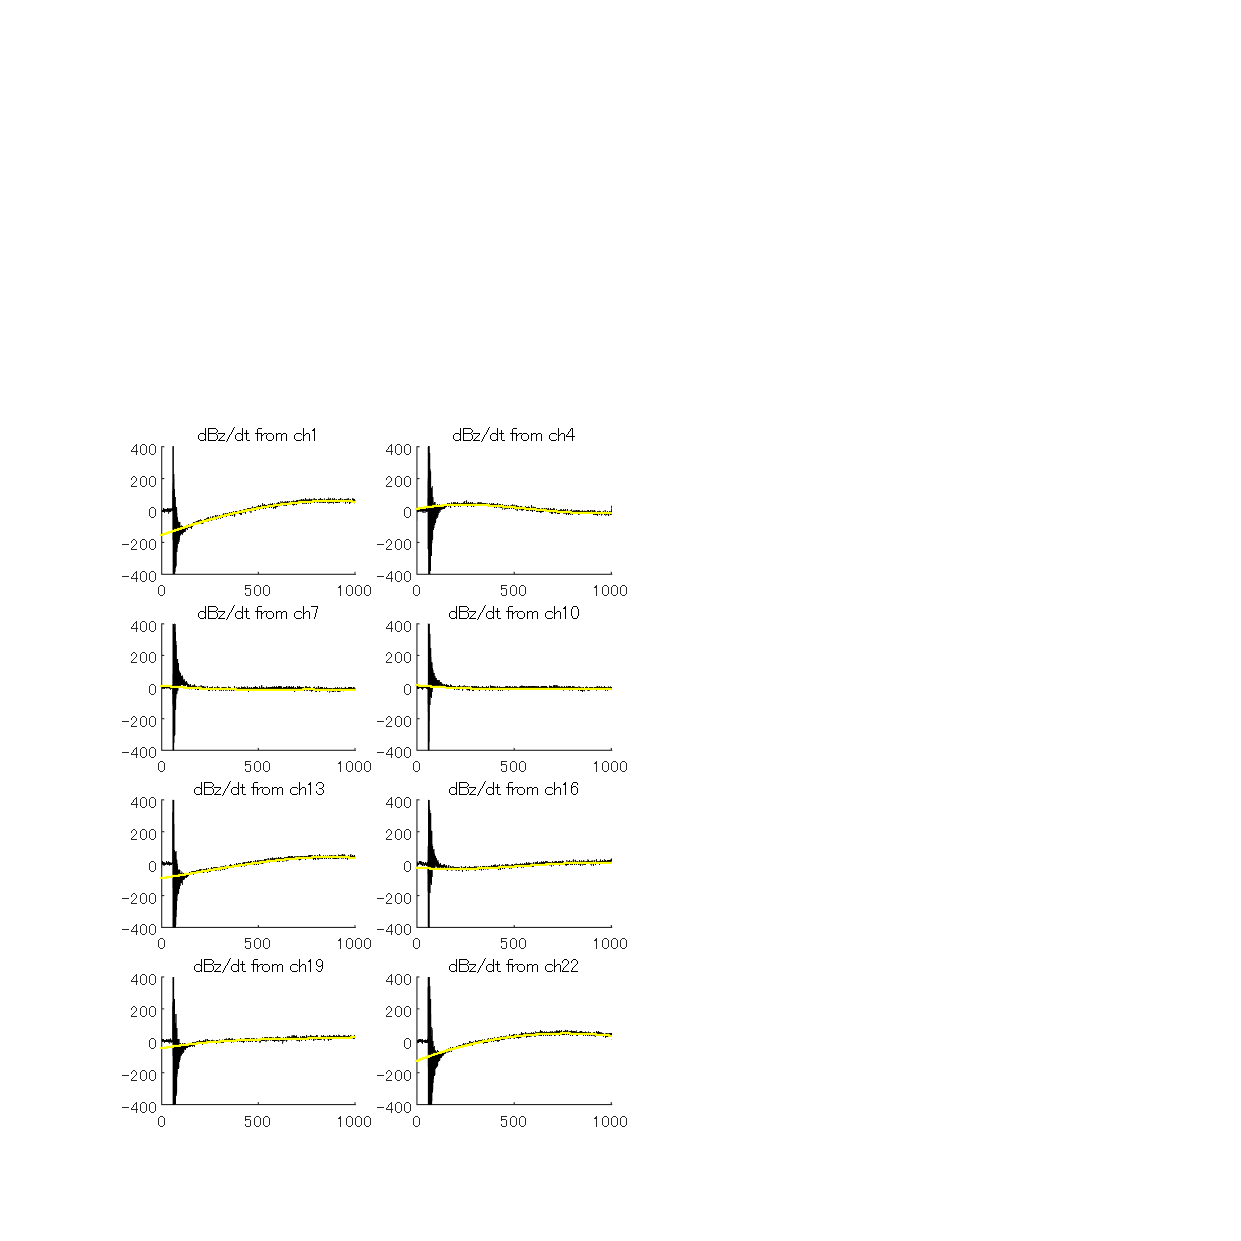

% TFのBz信号の3次式近似
n = 3;
% 係数保存用
p = zeros(n+1,8);
x = time_array([1500:3900,6500:10020]);
y = zeros(length(x),8);
fit_y = zeros(length(time_array),8);
t = time_array;


for i = 1:8
    %disp(i)
    index_bz = i*3-2;
    y(:,i) = dBdt_TF_only([1500:3900,6500:10020],index_bz);
    p(:,i) = polyfit(x,y(:,i),n);

    fit_y(:,i) = p(4,i)+p(3,i).*t+p(2,i).*t.*t+p(1,i).*t.*t.*t;

    subplot(4,2,i)
    hold on
    plot(time_array,smooth(dBdt_TF_only(:,index_bz),0.001),'k');
 
    scatter(time_array,fit_y(:,i),0.01,'y','.');
    
    ylim([-400 400]);
    title(['dBz/dt from ch',num2str(index_bz)])
    hold off
   
end

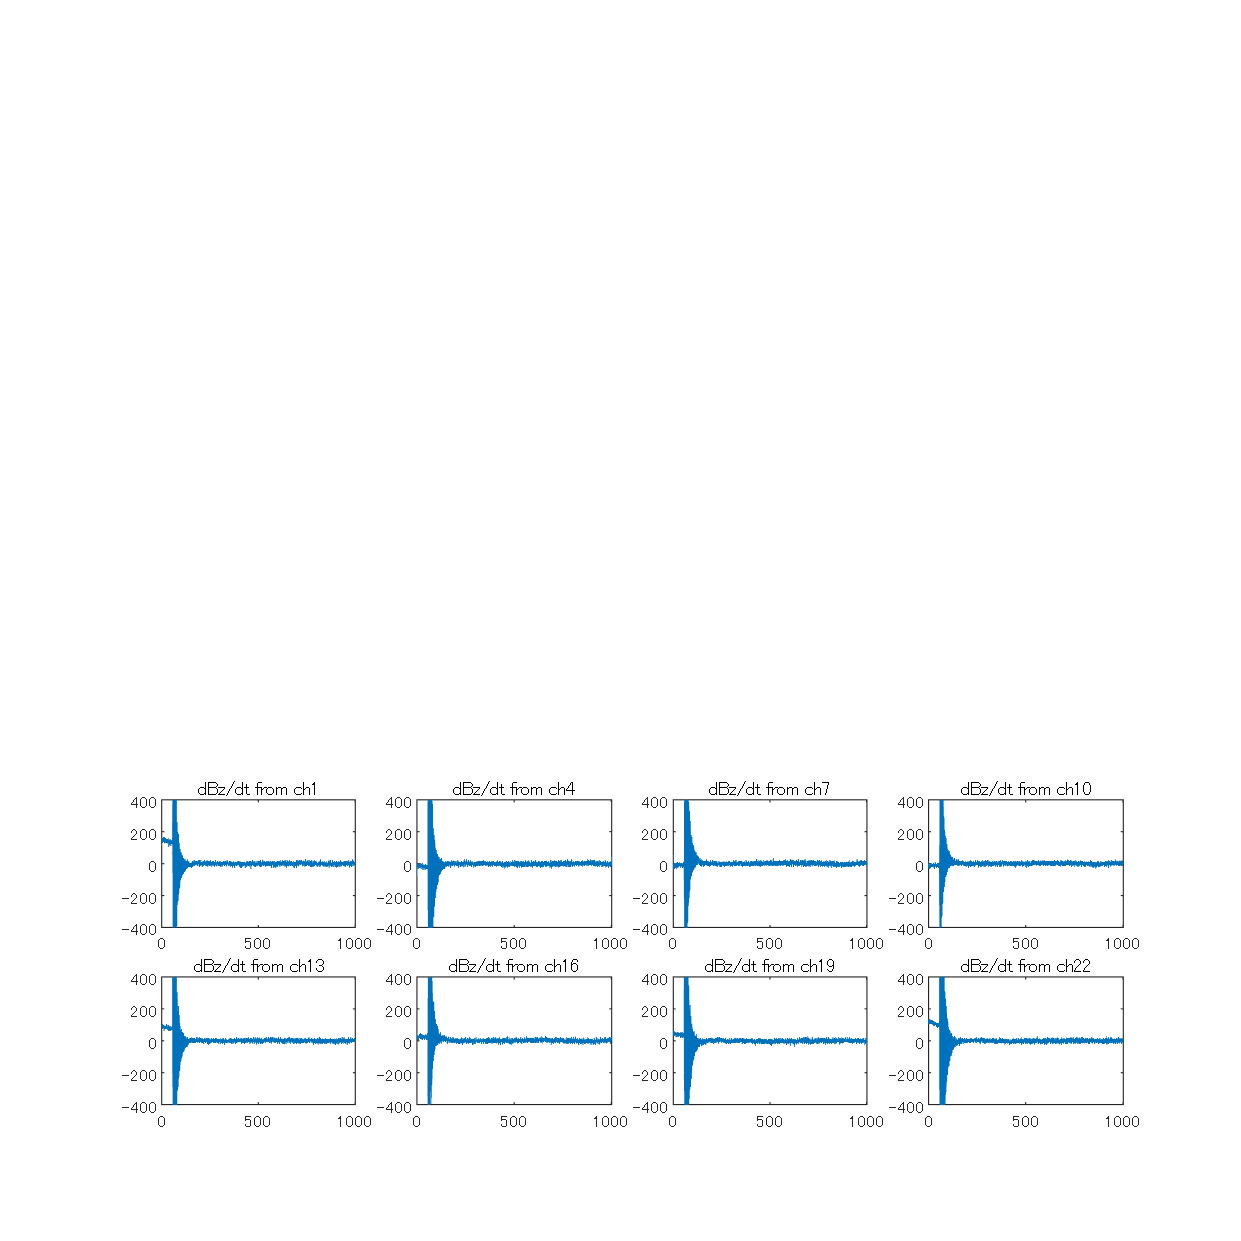

% TFのdBz/dt信号から近似式を引く
for i = 1:8
    index_bz = i*3-2;
    subplot(2,4,i)
    dBdt_TF_only(:,index_bz) = dBdt_TF_only(:,index_bz) - fit_y(:,i);
    plot(time_array,smooth(dBdt_TF_only(:,index_bz)));
    ylim([-400 400]);
    title(['dBz/dt from ch',num2str(index_bz)])
end
hold off

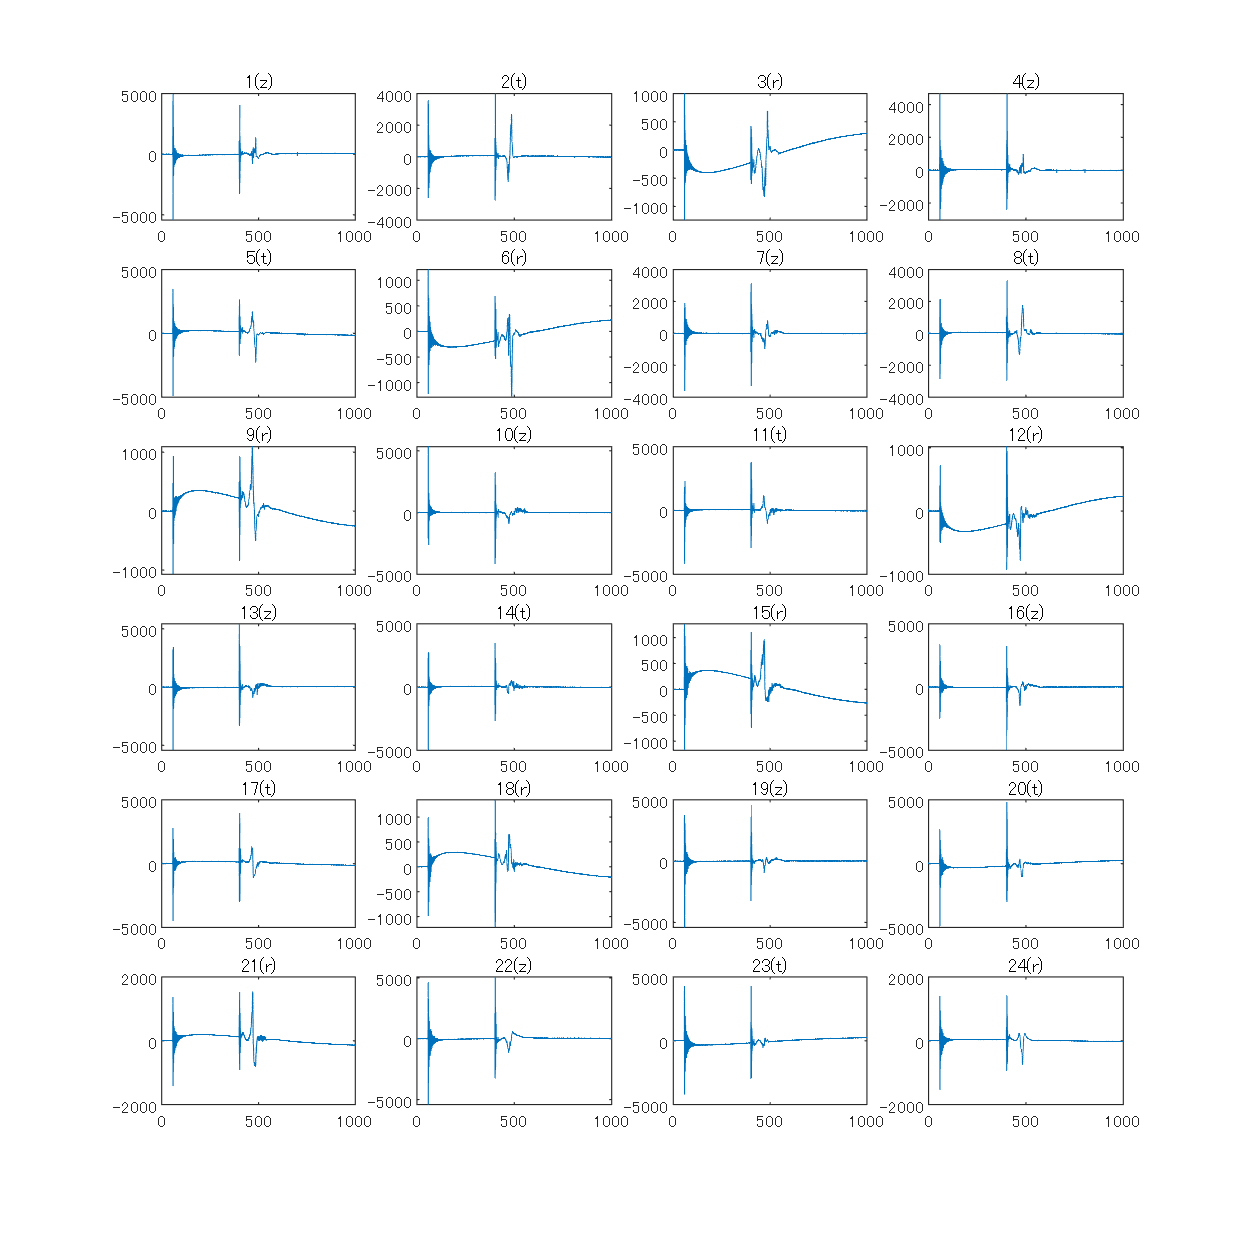

%%%%%%%%%%%　Bz_TF_only をノーマルショットから差し引く　%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% z t r
% plasmaあり　TF4kV PF39kV　shotの取得
date = 230119;
shot_num = 5;
raw_signal = read_datafile(shot_num,low_n_folder);
% rearrange to 1-24 in channel number according to labels on cable
dBdt = raw_signal(:,2:25)./calib_coefficient.*direction;
% 微分信号のプロット
plot_all_ch(time_array,dBdt,t_start, t_end,y_lowerlim, y_upperlim,0.004);

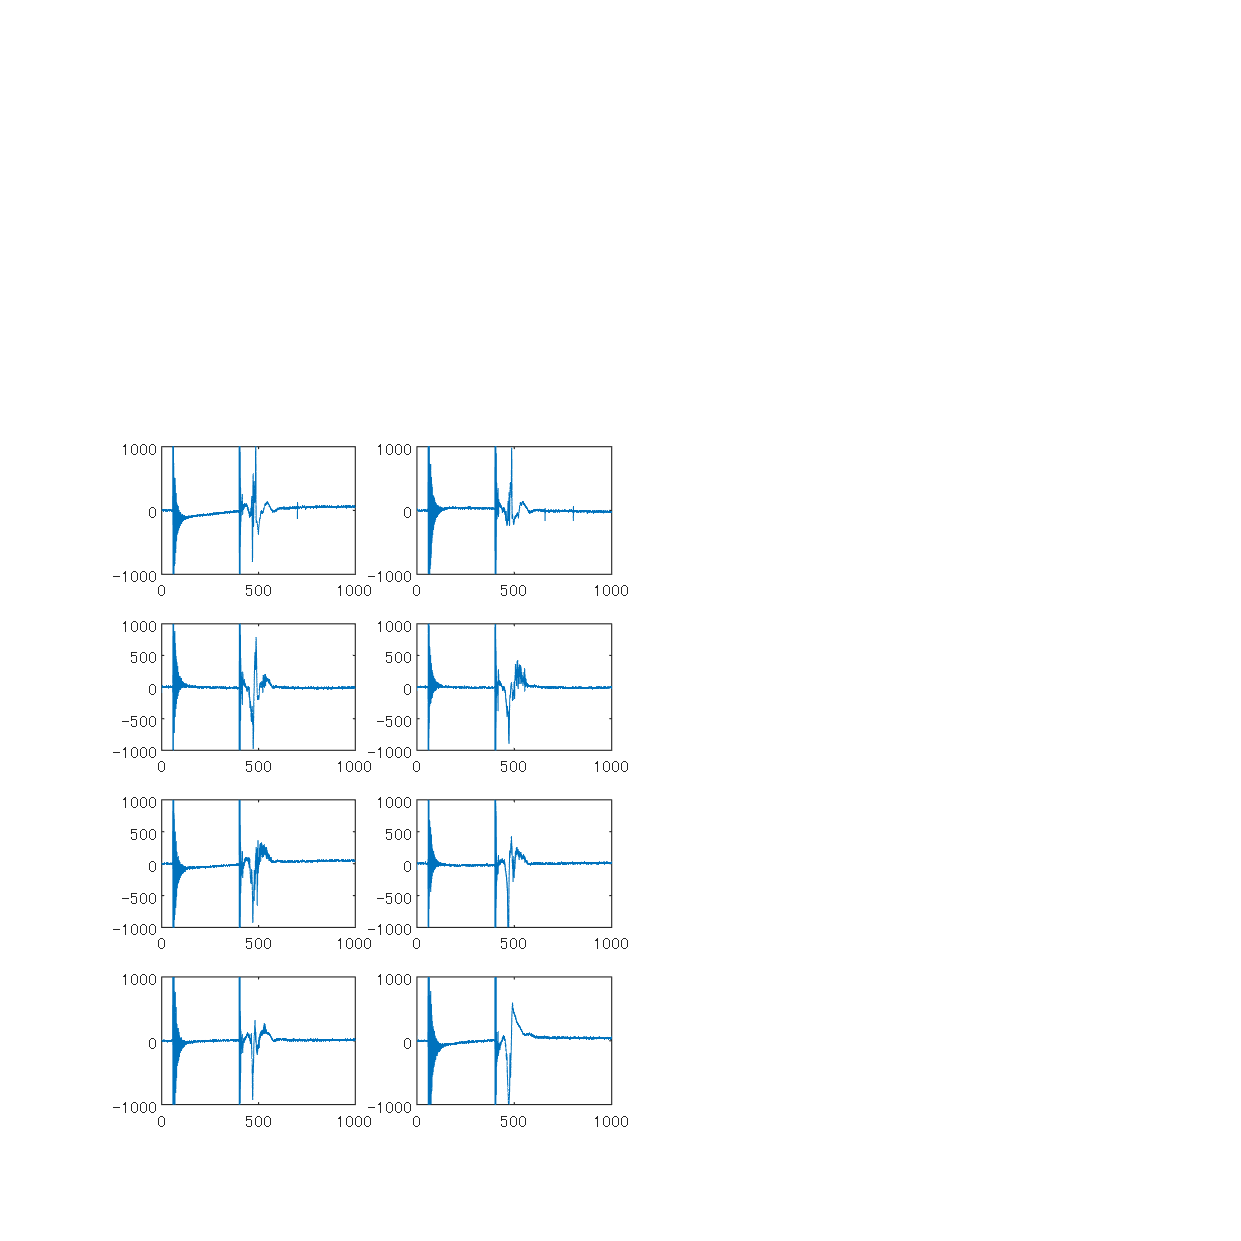

% dBz/dt生信号のみ保存&プロット
dBzdt = zeros(length(time_array), 8);
for i = 1:8
    index_bz = i*3-2;


    dBzdt(:,i) = dBdt(:,index_bz);
    subplot(4,2,i)
    hold off
    plot(time_array, smooth(dBzdt(:,i)))
    xlim([0 1000])
    ylim([-1000 1000])
    
end

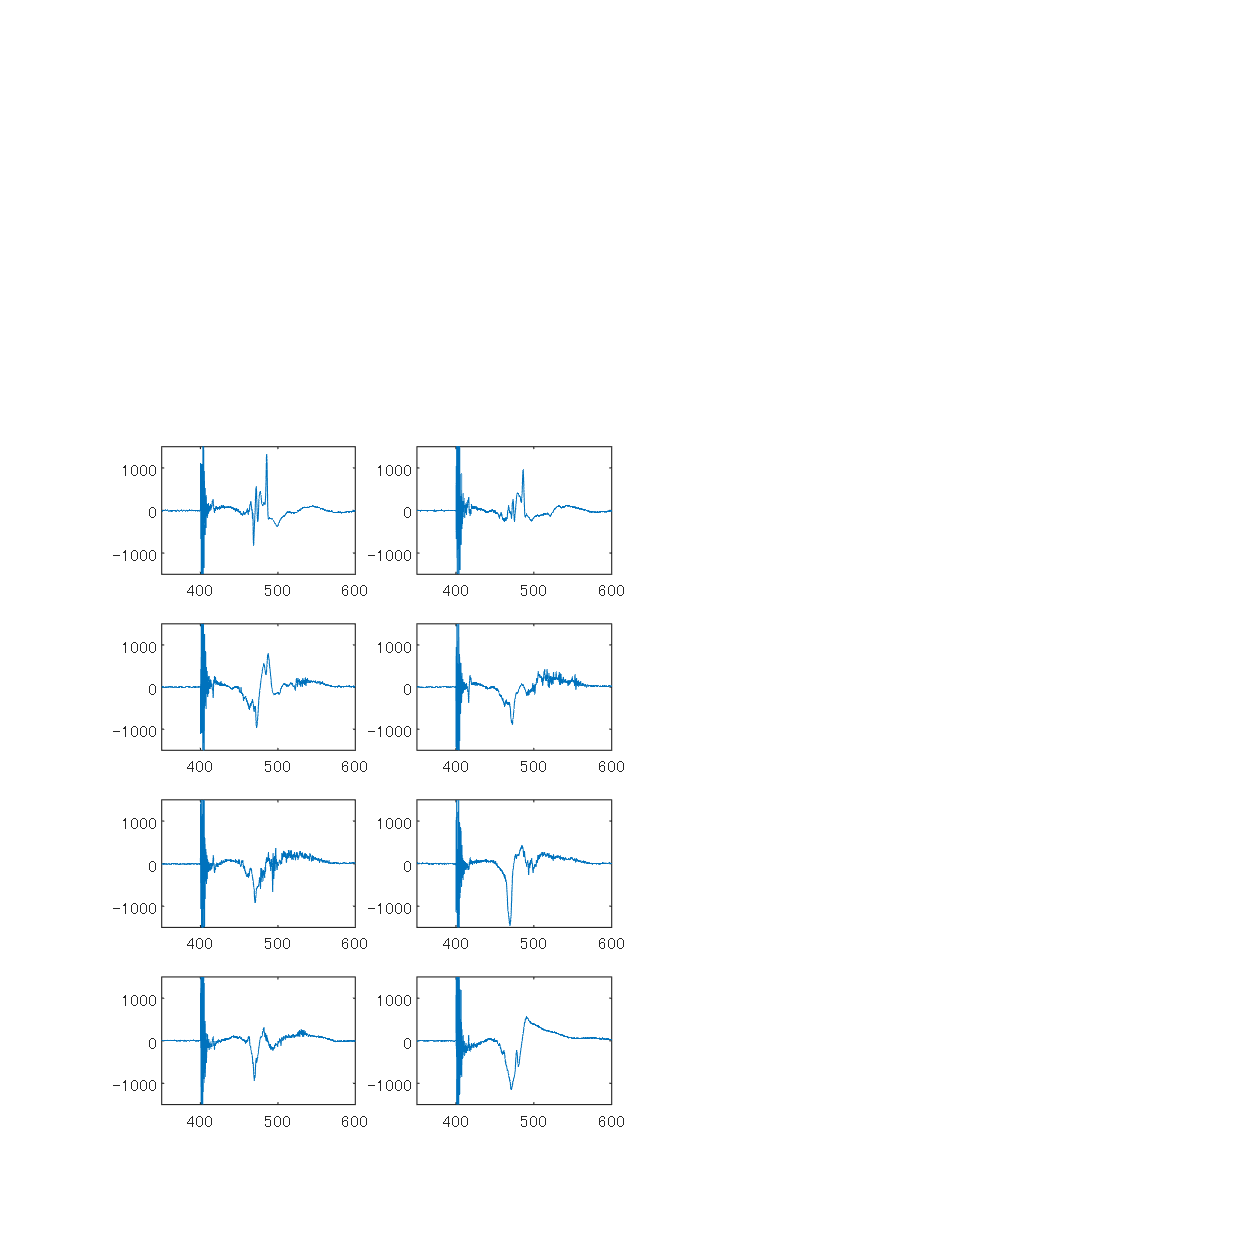




% offsetの波形を引いておく
    for i =1:8
        dBzdt(600:10020,i) = dBzdt(600:10020,i)-fit_y(600:10020,i);
    end
% 差し引いた信号のプロット

    for i = 1:8
        subplot(4,2,i)
        hold off
        plot(time_array, smooth(dBzdt(:,i)))
        xlim([350 600])
        ylim([-1500 1500])

    end

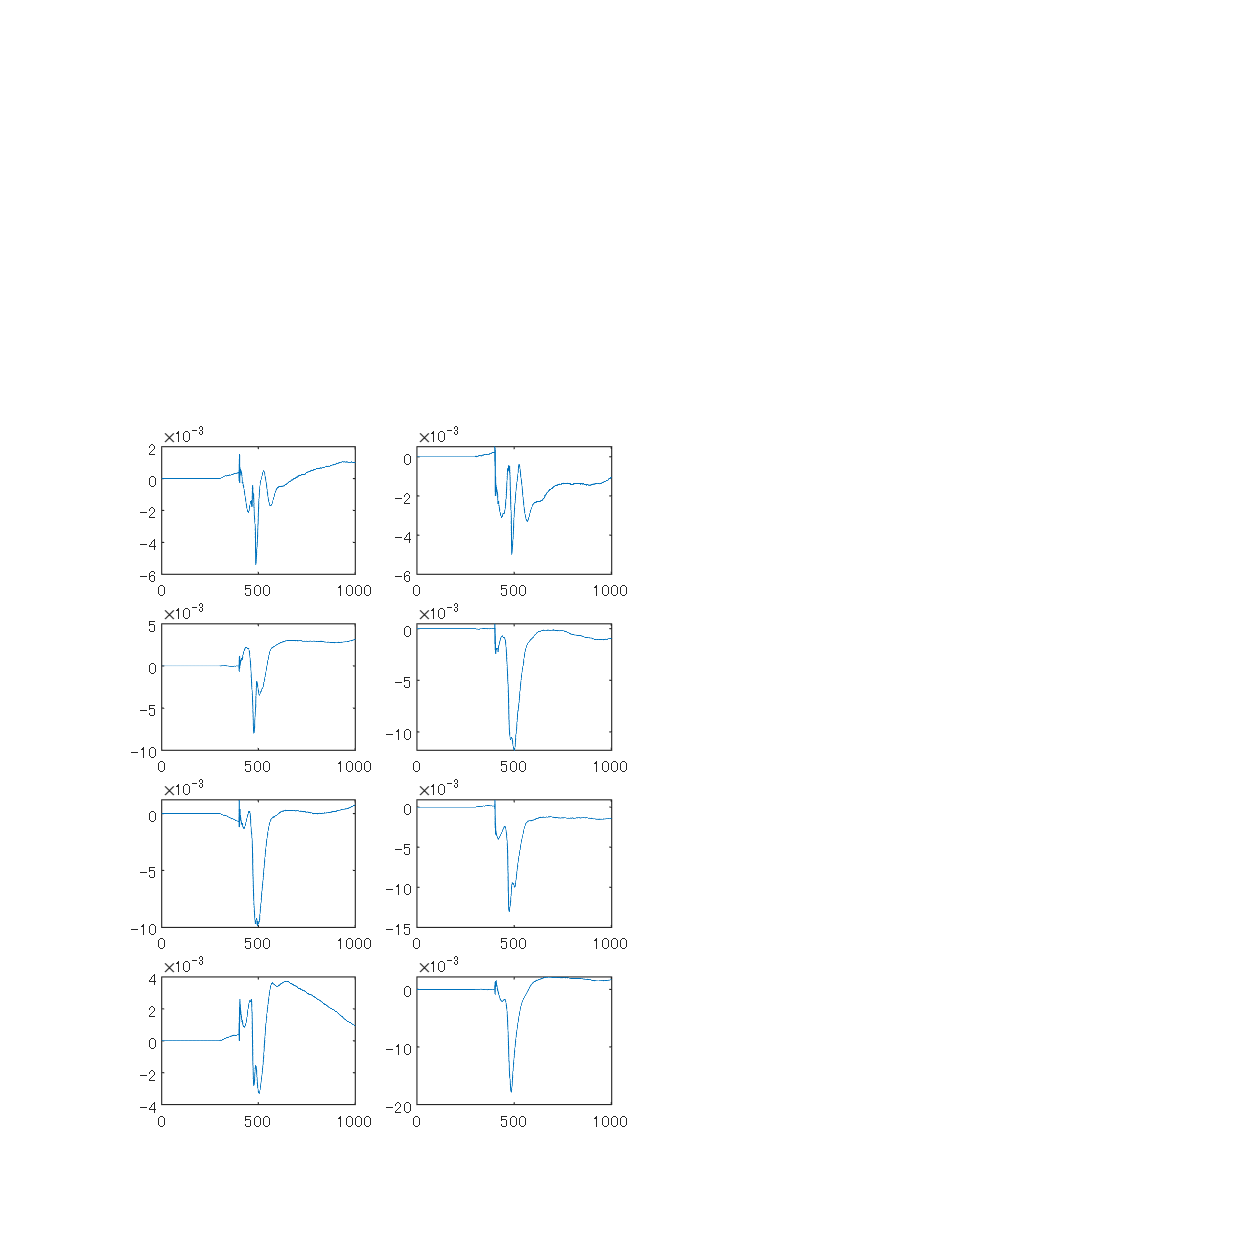

%　PFスタート付近から積分
% 数値積分Bz

dt = 10^-7;
Bz = zeros(length(time_array),8);
for i = 1:8
    index_bz = i*3-2;
    % 数値積分
    %Bz(4200:end,i) = cumtrapz(dBzdt(4200:end,i)*dt);
    Bz(3000:end,i) = cumtrapz(dBzdt(3000:end,i)*dt);
    if (i == 1 || i == 2)
        Bz(:,i) = Bz(:,i)*-1;

    end

   
    subplot(4,2,i)
    plot(time_array, Bz(:,i))
end

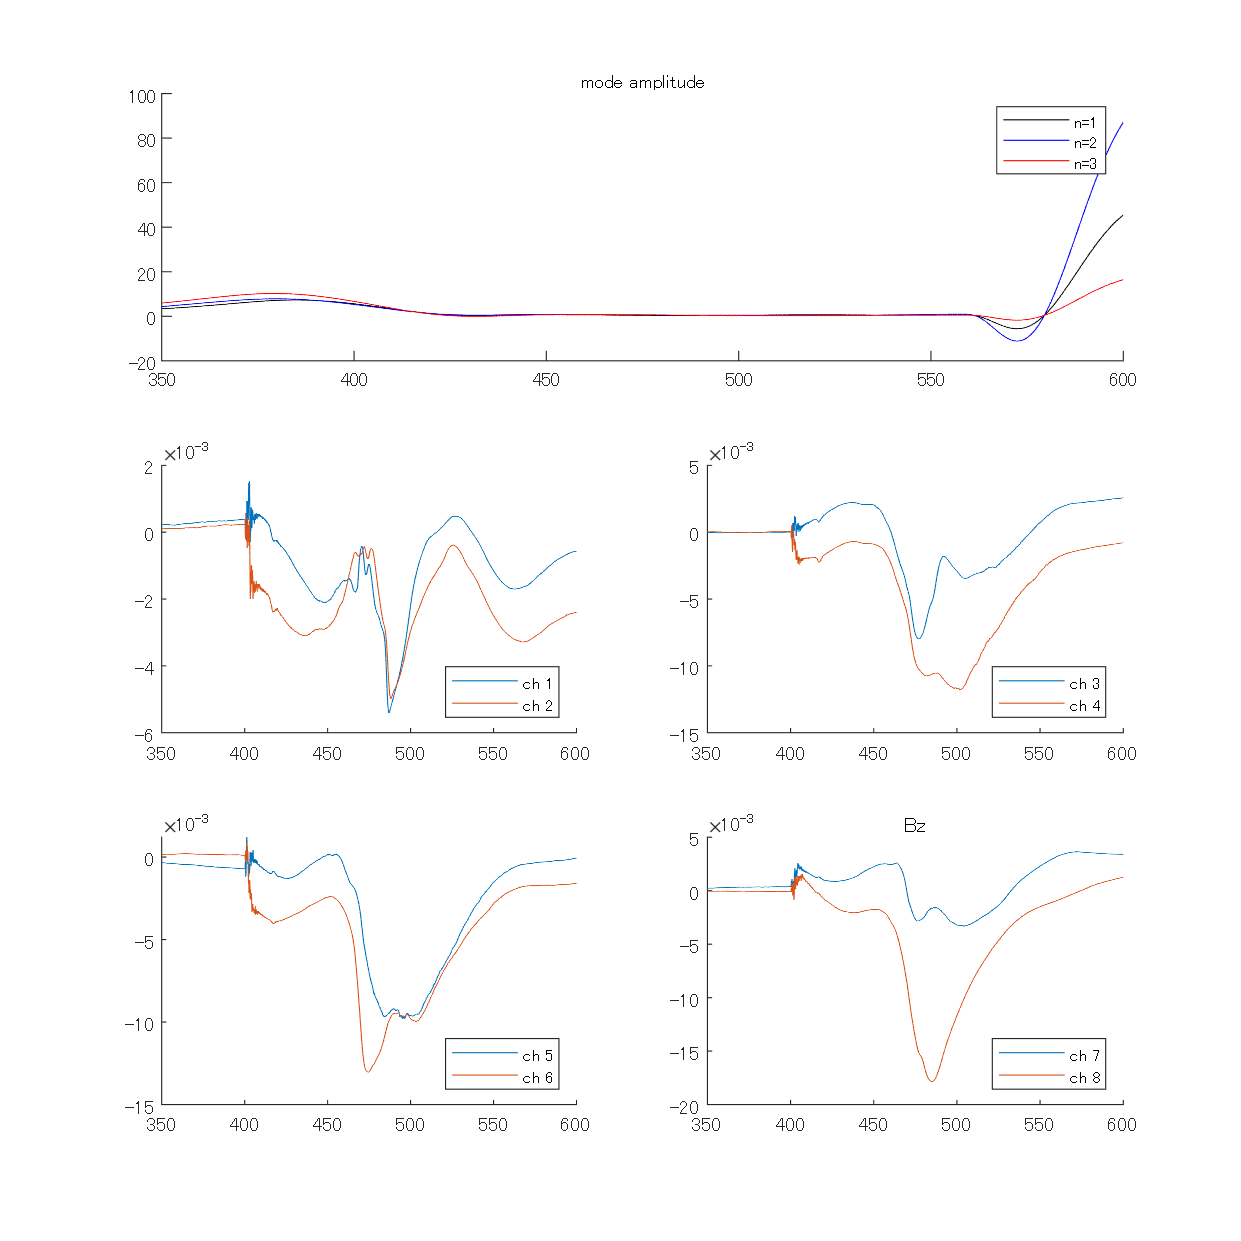

x = [0,4/24,7/24,9/24,12/24,15/24,17/24,20/24]; % non-uniform probe placement
%t = time_array(3500:6000);
t = time_array;

%measured_dBzdt = measured_dBzdt(3500:6000,:);
[n_Amp,n_Ph] = toroidal_mode(t,x,Bz); % get amplitude and phase
% calculate frequency from phase (smoothed)
%n1_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(1,:)),0.1,'loess'));
%n2_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(2,:)),0.1,'loess'));
%n3_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(3,:)),0.1,'loess'));
% *************** plotting ***************
figure('Position', [0 0 800 800]);
subplot(3,2,[1,2])
hold on
%plot(t,n_Amp(1,:));
%plot(t,n_Amp(2,:),'k');
%plot(t,n_Amp(3,:),'b');
%plot(t,n_Amp(4,:),'r');
%legend('n=0','n=1','n=2','n=3');
plot(t,smooth(n_Amp(2,:)./n_Amp(1,:),0.1,'loess'),'k');
plot(t,smooth(n_Amp(3,:)./n_Amp(1,:),0.1,'loess'),'b');
plot(t,smooth(n_Amp(4,:)./n_Amp(1,:),0.1,'loess'),'r');
legend('n=1','n=2','n=3');

%legend('n=1','n=2','n=3');
%ylim([-0.1 0.3]);
xlim([350 600])
title('mode amplitude')
hold off

for i = 1:4
    subplot(3,2,2+i)
    hold on
    plot(t,Bz(:,i*2-1));
    
    plot(t,Bz(:,i*2))
    xlim([350 600]);
    

    legend(['ch ',num2str(i*2-1)],['ch ',num2str(i*2)],'Location','southeast')
   

    hold off
    
end
    title('Bz')
%積分信号のプロット

%xlim([t_start t_end])
%ylim([y_lowerlim y_upperlim])
%ylim([0 2000])
hold off

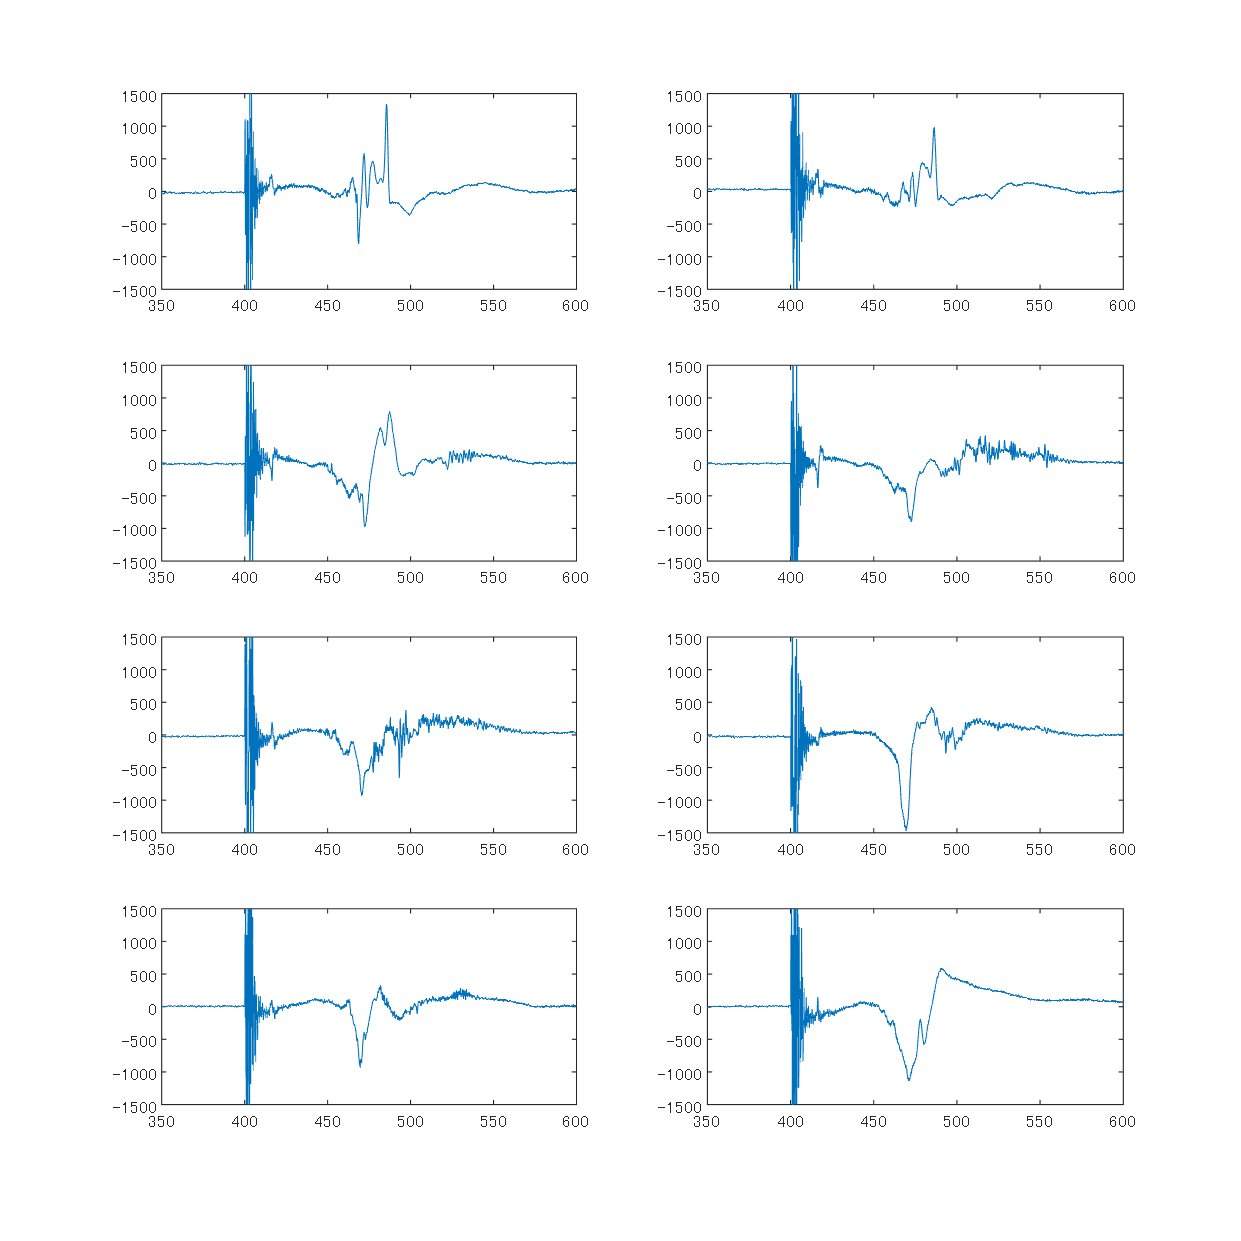

% dBz/dt生信号のみ保存&プロット
dBzdt = zeros(length(time_array), 8);
for i = 1:8
    index_bz = i*3-2;


    dBzdt(:,i) = dBdt(:,index_bz);
    subplot(4,2,i)
    hold off
    plot(time_array, smooth(dBzdt(:,i)))
    xlim([350 600])
    ylim([-1500 1500])
    
end

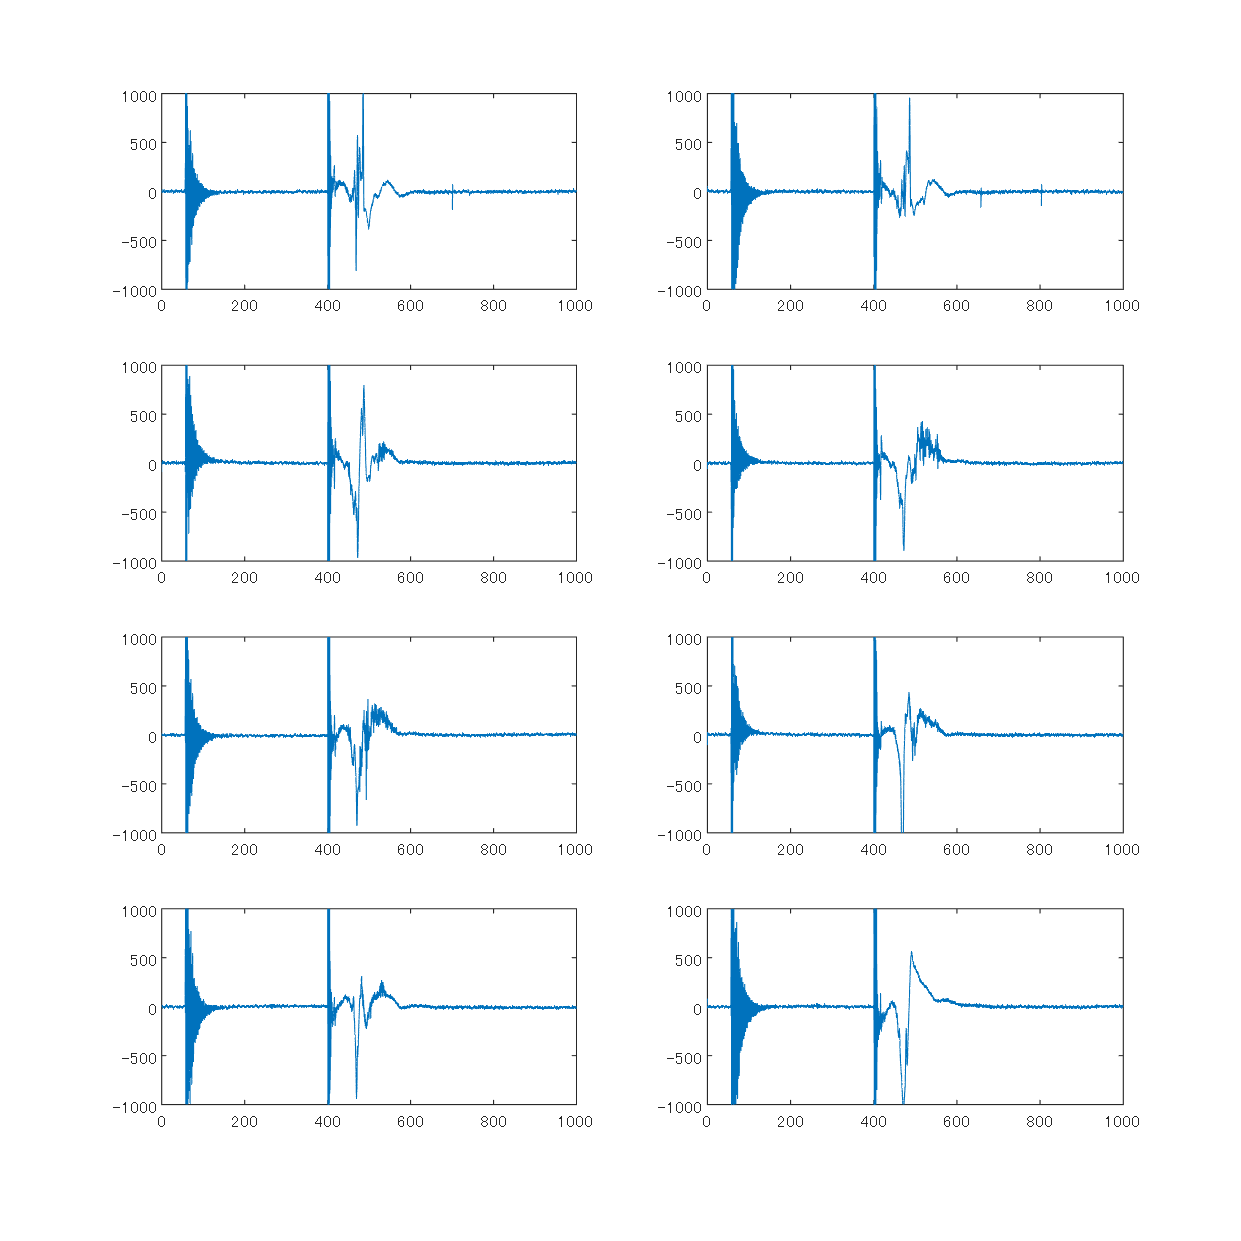



% offsetの波形を引いておく
    for i =1:8
        dBzdt(600:10020,i) = dBzdt(600:10020,i)-fit_y(600:10020,i);
    end
% 差し引いた信号のプロット
    for i = 1:8
        subplot(4,2,i)
        hold off
        plot(time_array, smooth(dBzdt(:,i)))
        xlim([0 1000])
        ylim([-1000 1000])

    end





dt = 10^-7;


%スタートのノイズを減らす
for i = 1:8
    for t = 4000:4100
        if(dBzdt(t,i) > 110 || dBzdt(t,i)< -110)
            dBzdt(t,i) = 0;
        end

    end

end


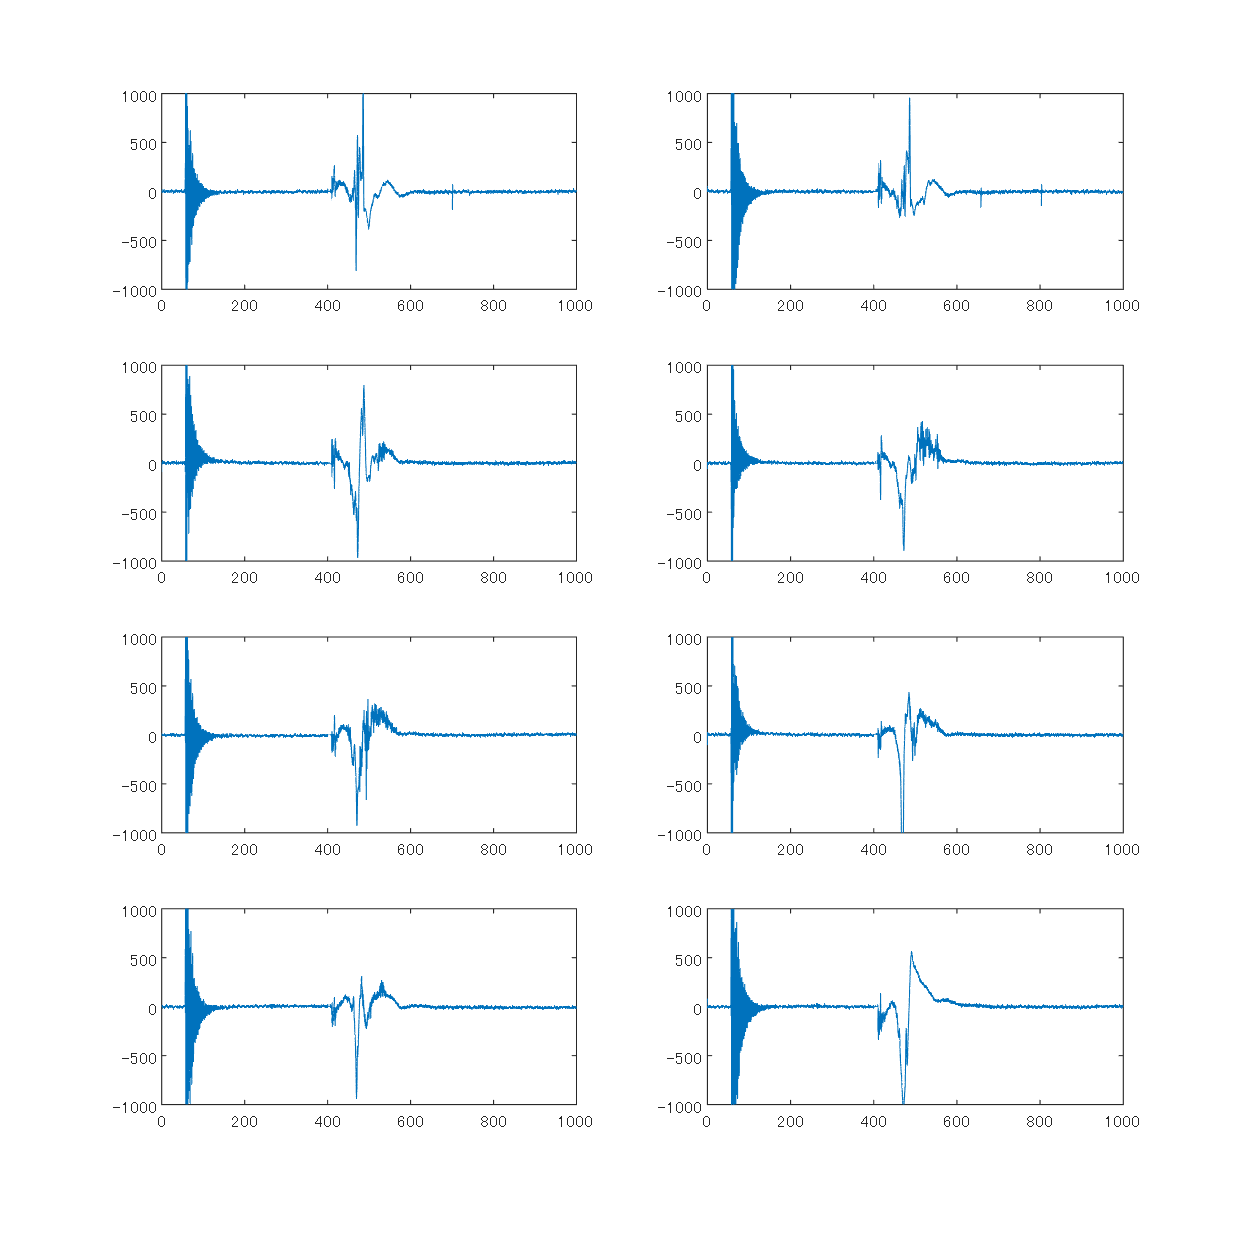

  for i = 1:8
        subplot(4,2,i)
        hold off
        plot(time_array, smooth(dBzdt(:,i)))
        xlim([0 1000])
        ylim([-1000 1000])

    end

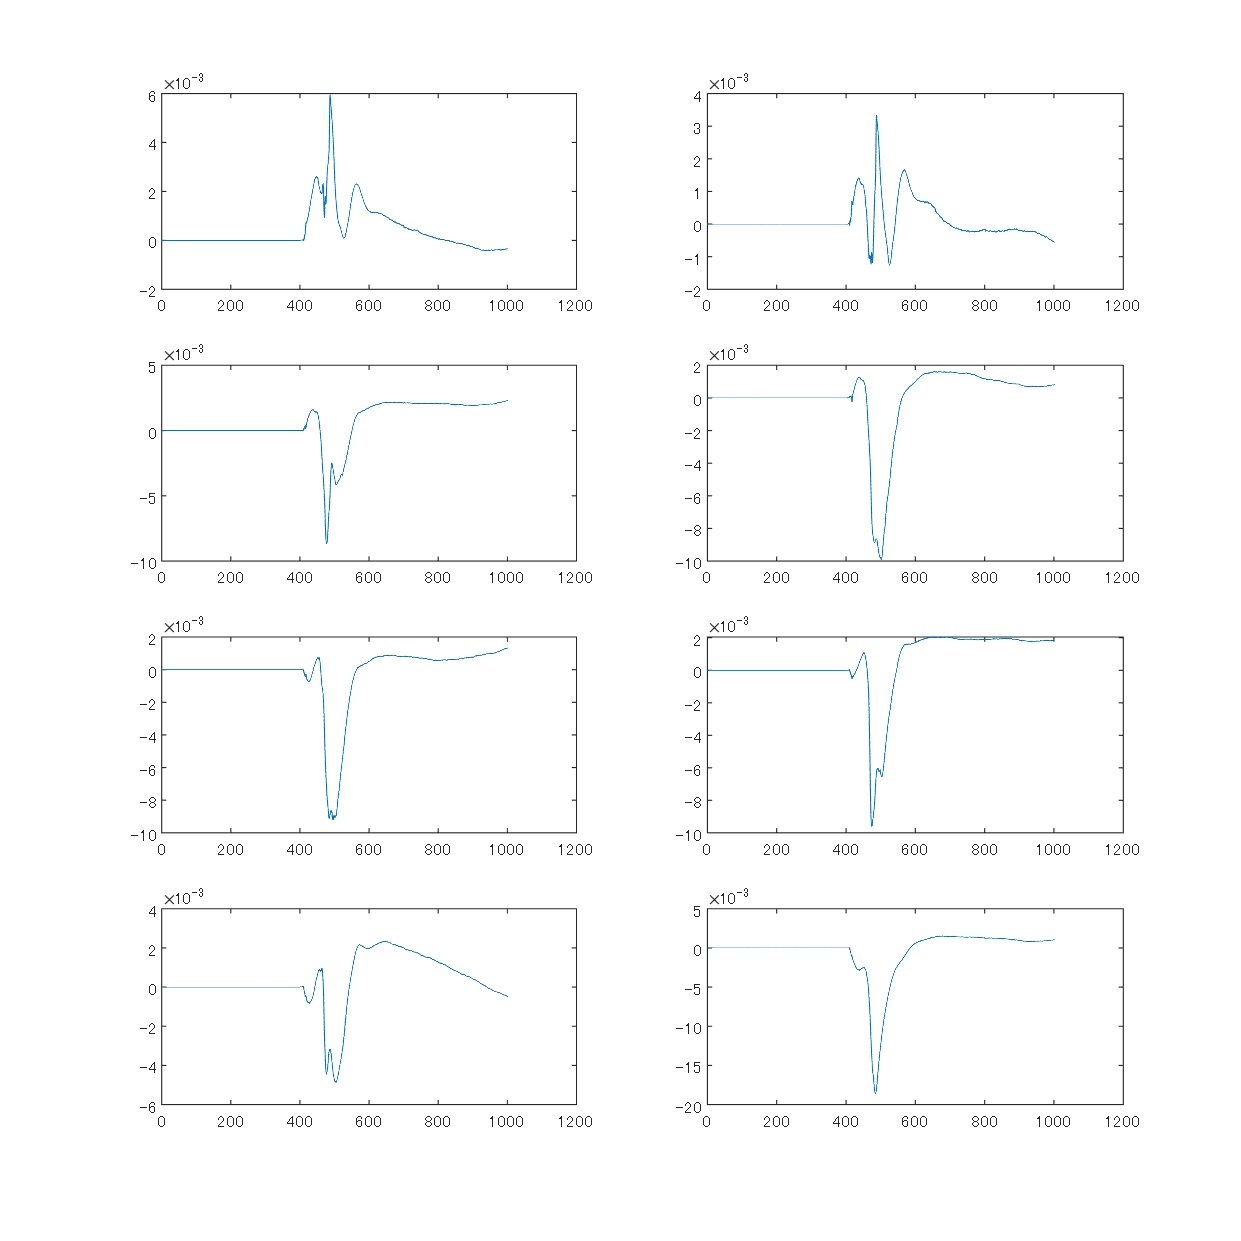



for i = 1:8
    
    index_bz = i*3-2;
    % 数値積分
    Bz(4000:10020,i) = cumtrapz(dBzdt(4000:10020,i)*dt);
    


    subplot(4,2,i)
    plot(time_array, Bz(:,i))
end

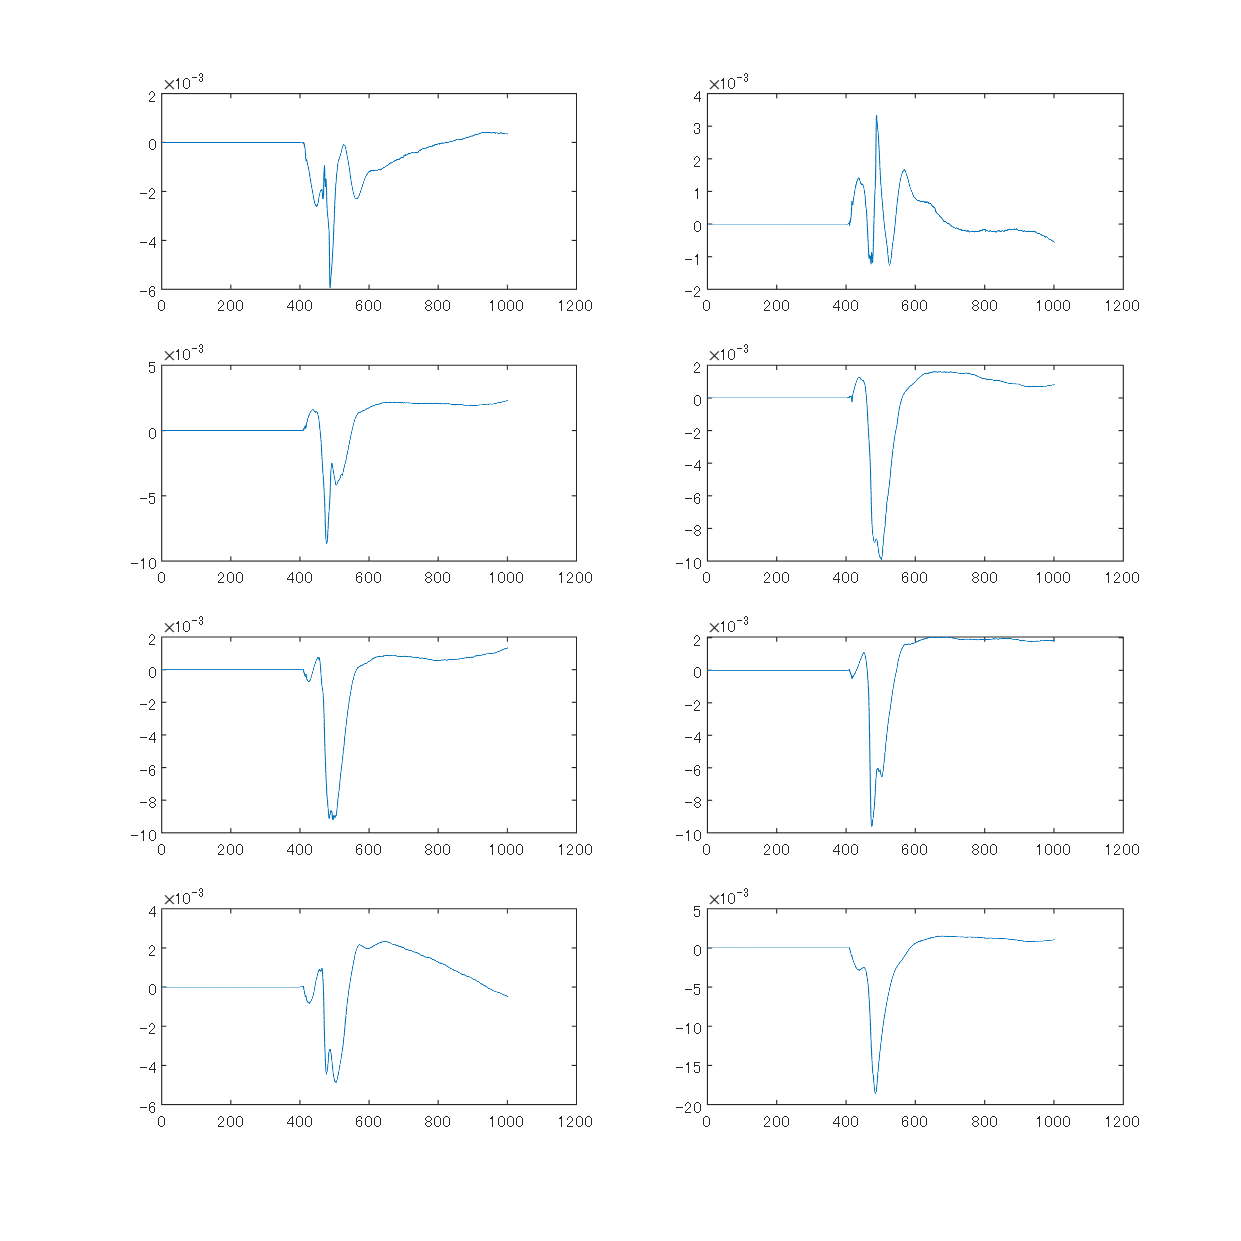


%放電前時間でオフセットを引いてみる

for i = 1:8

    % 正負そろえる
    if i == 1 
        Bz(:,i) = Bz(:,i)*-1;
    end
    
    subplot(4,2,i)
    plot(time_array, Bz(:,i))

end

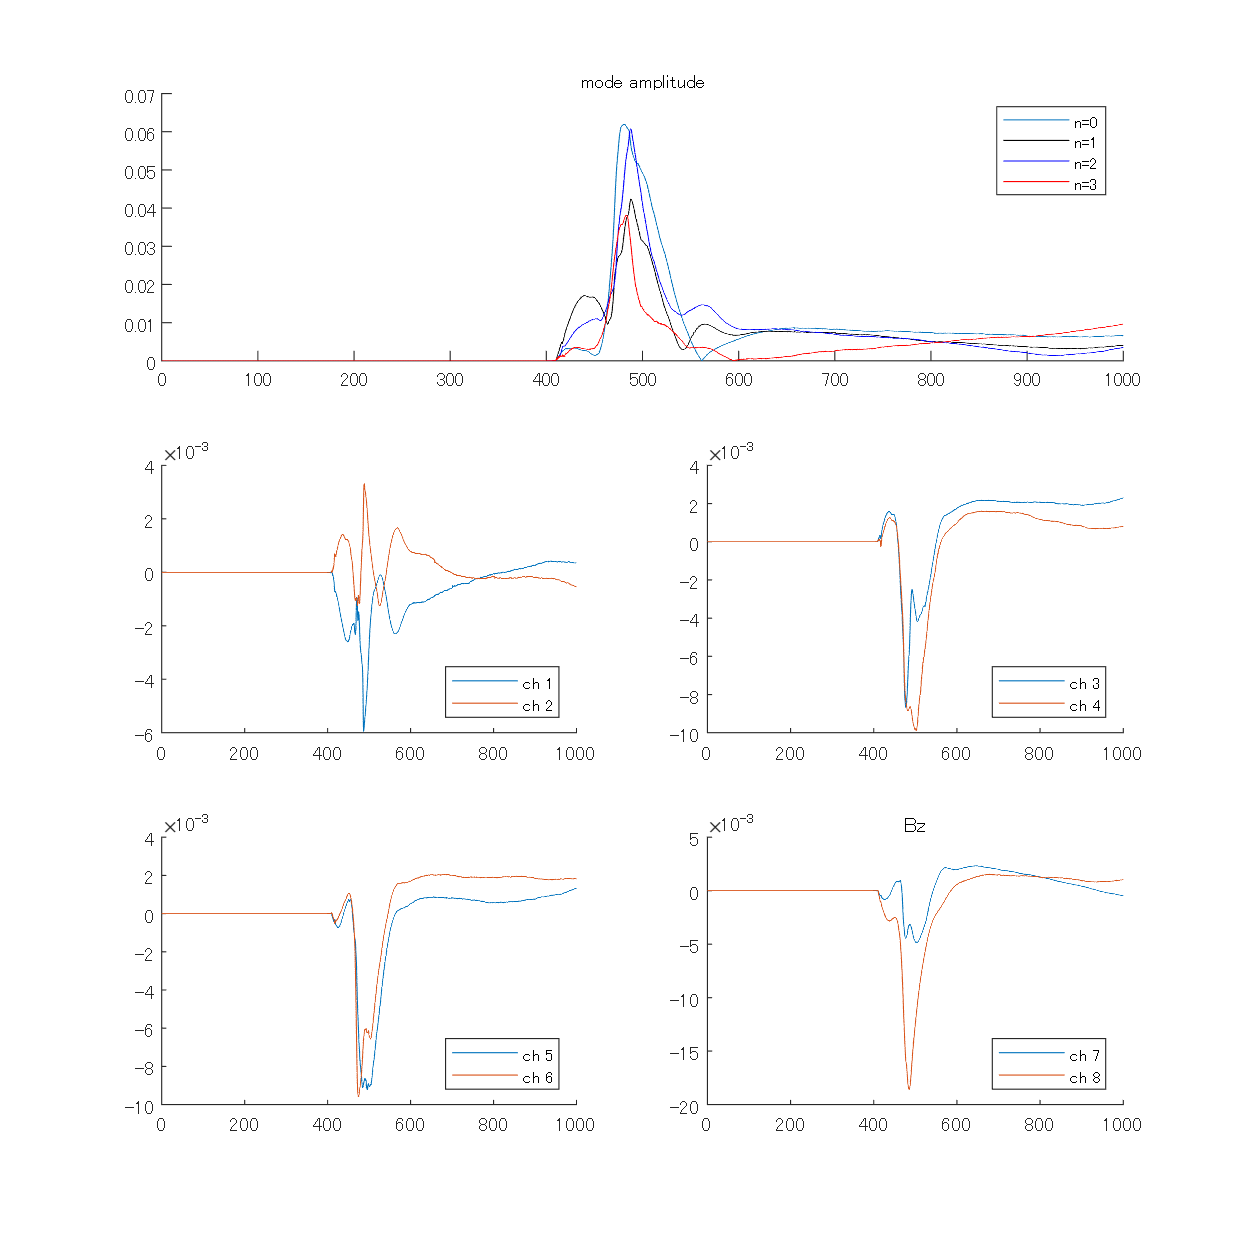

x = [0,4/24,7/24,9/24,12/24,15/24,17/24,20/24]; % non-uniform probe placement
%t = time_array(3500:6000);
t = time_array;

%measured_dBzdt = measured_dBzdt(3500:6000,:);
[n_Amp,n_Ph] = toroidal_mode(t,x,Bz); % get amplitude and phase
% calculate frequency from phase (smoothed)
%n1_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(1,:)),0.1,'loess'));
%n2_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(2,:)),0.1,'loess'));
%n3_Omega = calculate_omega(smooth(cumulative_phase(n_Ph(3,:)),0.1,'loess'));
% *************** plotting ***************
figure('Position', [0 0 800 800]);
subplot(3,2,[1,2])
hold on
plot(t,n_Amp(1,:));
plot(t,n_Amp(2,:),'k');
plot(t,n_Amp(3,:),'b');
plot(t,n_Amp(4,:),'r');
legend('n=0','n=1','n=2','n=3');
%plot(t,smooth(n_Amp(2,:)./n_Amp(1,:),0.1,'loess'),'k');
%plot(t,smooth(n_Amp(3,:)./n_Amp(1,:),0.1,'loess'),'b');
%plot(t,smooth(n_Amp(4,:)./n_Amp(1,:),0.1,'loess'),'r');
%legend('n=1','n=2','n=3');

%legend('n=1','n=2','n=3');
%ylim([-0.1 0.3]);
xlim([t_start t_end])
title('mode amplitude')
hold off

for i = 1:4
    subplot(3,2,2+i)
    hold on
    plot(t,Bz(:,i*2-1));
    
    plot(t,Bz(:,i*2))
    xlim([t_start t_end]);
    

    legend(['ch ',num2str(i*2-1)],['ch ',num2str(i*2)],'Location','southeast')
   

    hold off
    
end
    title('Bz')
%積分信号のプロット

%xlim([t_start t_end])
%ylim([y_lowerlim y_upperlim])
%ylim([0 2000])
hold off